The code in this assignment was developed in collaboration with my group, group 23. Therefore there will be code that resembels theirs.

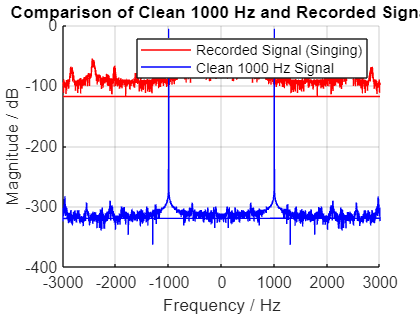

% Clear any previous figures
close all;

% First part: Generating and plotting the spectrum for the clean sinusoidal signal
fs = 48000;             % Sampling frequency
T = 10;                 % Duration in seconds

% Generate a 1000 Hz sinusoidal signal
[x_values, y_values] = generate_sinusoid(1, 1000, 0, fs, 0.5);  % amplitude=1, freq=1000Hz, phase=0, sampling freq=fs, time=0.5s
[Y_clean, freq] = make_spectrum(y_values, fs);  % Compute the spectrum of the clean sinusoidal signal

% Second part: Reading and processing the recorded signal
[signal, fs] = audioread('iii1000hz.wav');  % Read the recorded signal

% If stereo, convert to mono
if size(signal, 2) == 2
    signal = mean(signal, 2);  % Convert stereo to mono by averaging the channels
end

% Compute the spectrum of the recorded signal (using the last 24000 samples)
[Y_rec, freq] = make_spectrum(signal(end-24000+1:end), fs); 

% Now combine both stem plots in one figure

% Open a new figure for plotting
figure;
hold on; % Hold on for multiple plots

% Plot the plot for the recorded signal (red color)
plot(freq, 20*log10(abs(Y_rec)),'r'); % Recorded signal


% Plot the stem plot for the clean 1000 Hz sinusoidal signal (blue color)
plot(freq, 20*log10(abs(Y_clean)),'b');  % Clean sinusoidal signal

% Set axis limits for better visibility
xlim([-3000 3000]);  % Set x-axis limits from -3000 Hz to 3000 Hz
%ylim([-0.1 0.6]);  % Set y-axis limits for amplitude

% Add labels and title
xlabel('Frequency / Hz');
ylabel('Magnitude / dB');
legend('Recorded Signal (Singing)', 'Clean 1000 Hz Signal');
title('Comparison of Clean 1000 Hz and Recorded Signal');
grid on;

hold off; % Release the hold on the figure

## Functions

Function to generate a sinusoid

function [time_vector, signal] = generate_sinusoid(a, f, phi, fs, T_s)
    % Generates a sinusoidal signal
    time_vector = 0:1/fs:T_s-1/fs;  % Time vector (duration T_s)
    signal = a * cos(2 * pi * f * time_vector + phi);  % Sinusoidal signal
end

Function definition (spectrum calculation)

function [Y, freq] = make_spectrum(signal, fs)
    % Compute the FFT of the signal (complex-valued)
    Y = fft(signal);
    
    % Normalize the FFT by the length of the signal
    Y = Y / length(Y);    

    % Frequency resolution
    N = length(signal);           % Number of samples
    T0 = N / fs;                  % Duration of signal in seconds
    delta_f = 1 / T0;             % Frequency resolution

    % Frequency vector (positive and negative frequencies)
    if mod(N, 2) == 0
        % FOR EVEN NUMBER OF SAMPLES
        f_pos = 0:delta_f:fs/2;    % Positive frequencies up to fs/2
        f_neg = -fs/2+delta_f:delta_f:-delta_f; % Negative frequencies
    else
        % FOR ODD NUMBER OF SAMPLES
        f_pos = 0:delta_f:(floor(N/2) * delta_f); % Up to just below Nyquist
        f_neg = -(floor(N/2)) * delta_f:delta_f:-delta_f; % Negative frequencies
    end

    % Combine positive and negative frequencies
    freq = [f_pos f_neg];

    % Convert FFT result to decibels if needed
    % Y = 20 * log10(abs(Y));  % Optionally apply dB scale here

    % Convert to column vectors if necessary
    Y = Y(:);
    freq = freq(:);
end
